# Auto-generated by Data Acquisition Toolbox Analog Input Recorder on 16-Jul-2020 14:01:01

## Create DataAcquisition Object

Create a DataAcquisition object for the specified vendor.

d = daq("ni");

## Add Channels

Add channels and set channel properties, if any.

ch1 = addinput(d,"Dev1","ai0","Voltage");
ch1.Name = "shutter";
ch1.Range = [-5 5];

ch2 = addinput(d,"Dev1","ai1","Voltage");
ch2.Name = "arm";
ch2.TerminalConfig = "SingleEnded";

ch3 = addinput(d,"Dev1","ai2","Voltage");
ch3.Name = "fire";

ch4 = addinput(d,"Dev1","ai4","Voltage");
ch4.Name = "testing";

## Set DataAcquisition Rate

Set scan rate.

d.Rate = 2000;

## Read Data

Read the data in timetable format.

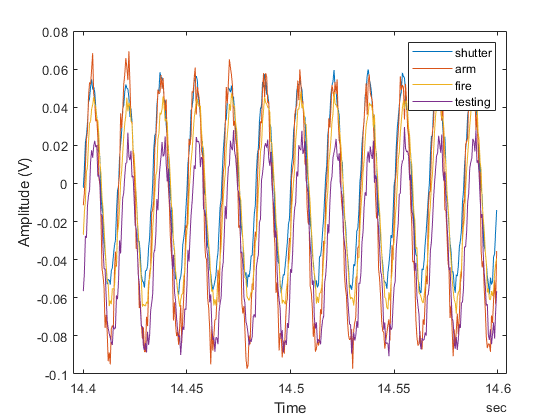

DAQ_3 = [];
n = ceil(d.Rate/10);

t = tic;
start(d,"continuous")
while toc(t) < 15 % Increase or decrease the pause duration to fit your needs.
    data = read(d,n);
    DAQ_3 = [DAQ_3; data];
    
    % Uncomment the following lines to enable live plotting.
    plot(data.Time, data.Variables)
    xlabel("Time")
    ylabel("Amplitude (V)")
    legend(data.Properties.VariableNames)
end

stop(d)

% Display the read data
DAQ_3

DAQ_3 = 29200×4 timetable
       Time        shutter         arm           fire        testing 
    __________    __________    __________    __________    _________

    0 sec          -0.041387      -0.07291     -0.031837    -0.092954
    0.0005 sec     -0.041716     -0.088354     -0.050566    -0.062395
    0.001 sec       -0.03958     -0.085068     -0.055166    -0.067653
    0.0015 sec     -0.048618     -0.080796     -0.055495    -0.084411
    0.002 sec       -0.04566      -0.09394      -0.06141    -0.080139
    0.0025 sec      -0.04073     -0.081782     -0.060095    -0.083096
    0.003 sec      -0.044674     -0.066667     -0.064695    -0.082439
    0.0035 sec     -0.038594     -0.0

## Plot Data

Plot the read data on labeled axes.

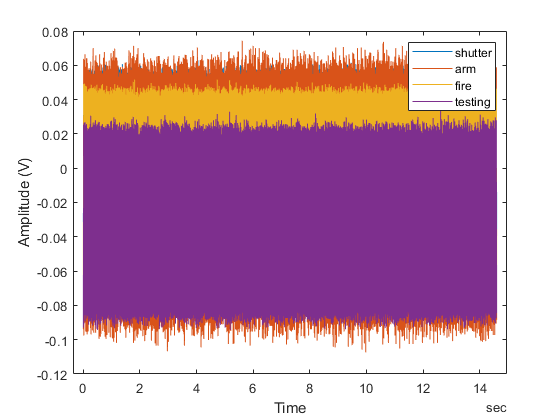

plot(DAQ_3.Time, DAQ_3.Variables)
xlabel("Time")
ylabel("Amplitude (V)")
legend(DAQ_3.Properties.VariableNames)

## Clean Up

Clear all DataAcquisition and channel objects.

clear d ch1 ch2 ch3 ch4